# Part 3: Experiment

## Testing the Effects of Potassium Concentration on Action Potential Curves

#### Abstract

The goal of this study was to use the Connor-Stevens model to investigate the influences of extracellular potassium concentration on action potentials. The investigation was initially motivated by a curiosity to understand the effects of drugs that block potassium channels. The purpose was to gain a better understanding of potassium's role in the action potential of a neuron so that more complex conductance based models can be used to study these drugs. This study uses the Nernst equation to calculate seven different potassium reversal potentials based on a given vector of various extracellular potassium concentrations. We found that a more negative potassium reversal potential led to a failure in generating action potentials. However, increasing the extracellular potassium current increases the number of spikes produced by the action potential. 

#### Question

What impact does the elevation of extracellular potassium ion concentration have on the shape of the action potential curve in the Connor-Stevens model?

#### Setting up the parameters

The parameters were taken from table 4.3 of Introductory Course in Computational Neuroscience textbook. The conductances for the neuron were slightly modified to change the units from μS to nS. Leak conductance $G_{\textrm{leak}} =30$nS, maximal sodium conductance $G_{\textrm{Na},\max }$= 12000 nS, maximal potassium conductance $G_{K,\max }$= 2000 nS and maximal A conductance $G_{A,\max } =4770$nS. The reversal potentials for sodium and the leak channels were also set up as they are constant in the experiment. The sodium reversal potential, $E_{\textrm{Na}}$ = 55 mV and the leak reversal potential $E_{\textrm{leak}}$= -17 mV. Finally membrance capacitance is $C_m =100$pF. 

%Define parameters, table 4.3 Introductory Course in Computational
%Neuroscience
% the maximum conductance values were slightly modified to change the units from μS to nS
G_leak = 30; %nS %leak conductance
G_Na_max = 12000; %nS 
G_K_max = 2000; %nS
G_A_max = 4770; %nS
E_Na = 55; %mV

E_leak = -17; %mV
C_m = 100; %pF

#### Setting up Time Vector

Various max time values were studied in the controled experiment to determine the best fit. Eventually, tmax was defined to be 150 ms as it ensures that the system has enough time to respond to changes in the potassium reversal potential without overcrowding the graph. Thus, a vector of time was created from 0 ms to 150 ms with a dt = 0.01 ms. 

%define time vector
dt = 0.01;
tmax = 150;
time = 0 : dt : tmax;


#### Setting up dynamic variables

The model uses differential equations to solve various variabels. Vectors for the membrane voltage, $V_m$, applied current, $I_{\textrm{app}}$, and the gating variabels are allocated to the same size as time. The membrane voltage is initialized to be the same as the leak conductance. The applied current is changed to 900 pA when time > 50 ms or time < 100 ms. The gating variables are initialized later in the for loop. 

%defining membrane voltage
V_m = zeros(size(time)); 
V_m(1) = E_leak; %initializing membrane voltage

%applied current is constant for know
I_app = zeros(size(time)) ;
change = time > 50 & time < 100;
I_app(change) = 900; %pA

%defining gating variables
m = zeros(size(time));
h = zeros(size(time));
n = zeros(size(time));
a = zeros(size(time));
b = zeros(size(time));

#### Finding $E_K$and $E_A$

Notice how the reversal potentials for the $K^+$ and $A$ channels were not initialized. This is a result of our dynamic extracellular potassium ion concentration, ${\left\lbrack K^+ \right\rbrack }_{\textrm{out}}$. Its vector $K_{\textrm{out}}$ was created from 6 mM to 12 mM with a concentration step, dK, of 1 mM and a typical external concentration of 6 mM. These values were specifically chosen after a careful review of the  Nernst potential in the *Introductory Course in Computational Neurosceince* textbook as well the journal article entitled *Extracellular Potassium Homeostasis: Insights from Hypokalemic Periodic Paralysis *that defines a normal potassium concentration range. The internal concentration of potassium was set to the constant 150 mM. 

The Nersnt equation was used to find $E_K$ where $E_K =\frac{k_b T}{z_K q_e }\ln \left(\frac{{\left\lbrack K^+ \right\rbrack }_{\textrm{out}} }{{\left\lbrack K^+ \right\rbrack }_{\textrm{in}} }\right)$. It uses the boltzman constant $k_b =1\ldotp 38*{10}^{-23} \;{\textrm{JK}}^{-1}$, the charge of electrons $q_e =1\ldotp 6*{10}^{-19} \;C$, temperature $T=310\;K$ as well as the charge of a potassium ion $z_K =1$ C. 

Additionally, the potassium concentration also affects the reversal potential of the *A* channel. Due to limited studies and formulas on the differences between the potassium and A channels, an assumption was made after evaulating several implementations of the model that the difference between their reversal potentials is minimal. As a result, $E_A$ was found by subtracting a value of 2 from each corresponding $E_K$ in the vector. 

% Nernst calculation
K_min = 6; %mM
K_max = 12; %mM
dK = 1; %mM
K_out = K_min : dK : K_max % vector of K concentrations

K_out =      6     7     8     9    10    11    12


K_in = 150; %mM
% constants for Nernst eqn
kB = 1.38e-23; % JK^-1 Boltzman constant
qe = 1.6e-19; % charge of electrons C
T = 310; % temperature in Kelvins
z_K = 1;
mV = 1000; % 1 volt has 1000 mV
% vector of Nernst potentials from concentrations
E_K = (((kB .* T) ./ (z_K .* qe)) .* log(K_out ./ K_in)) * mV %in mV

E_K =   -86.0647  -81.9431  -78.3728  -75.2236  -72.4065  -69.8581  -67.5317



%Reversal for A
E_A = E_K - 2;

Allocate ${\textrm{AP}}_{\textrm{peak}}$ to be a zeros vector with the same size as $E_K$. It stores the voltage at the peak of the action potential in each trial. This variable is later used in a graph against the various ${\left\lbrack K^+ \right\rbrack }_{\textrm{out}}$ values. 

AP_peak = zeros(size(E_K));

#### Creating the for loops

Create a nested for loop with the outer for loop running through the different values of $E_K$ and $E_A$ while the inner for loop running through the time vector. 

The voltage dependent formulas used are from *An Introductory Course in Computational Neuroscience *textbook. However, they were slightly modified to account for the changes in the conductance parameters as well as time.  

$A$ channels voltage dependent formulas:


$$

\[ a_{\text{inf}} = \left(0.0761 \cdot \frac{\exp(0.0314(V_m(t)+94.22))}{1+\exp(0.0346(V_m(t)+ 1.17))}\right)^{\frac{1}{3}} \]

\[ \tau_a = \frac{0.3632 + 1.158}{1+\exp(0.0497(V_m(t)+ 55.96))} \]

\[ b_{\text{inf}} = \left(\frac{1}{1+\exp(0.0688(V_m(t)+ 53.3))}\right)^4 \]

\[ \tau_b = \frac{1.24 + 2.678}{1+\exp(0.0624(V_m(t)+ 53.3))} \]
$$


Sodium channel voltage dependent variables: 


$$\[ \alpha_m = 0.38 \cdot \frac{V_m(t) + 29.7}{1 - \exp(-0.1 \cdot (V_m(t) + 29.7))} \]
\[ \beta_m = 15.2 \cdot \exp(-0.0556 \cdot (V_m(t) + 54.7)) \]
\[ \alpha_h = 0.266 \cdot \exp(-0.05 \cdot (V_m(t) + 48)) \]
\[ \beta_h = \frac{3.8}{1 + \exp(-0.1 \cdot (V_m(t) + 18))} \]
$$


Potassium channel voltage dependent variables: 


$$\[ \alpha_n = 0.02 \cdot \frac{V_m(t) + 45.7}{1 - \exp(-0.1 \cdot (V_m(t) + 45.7))} \]
\[ \beta_n = 0.25 \cdot \exp(-0.0125 \cdot (V_m(t) + 55.7)) \]
$$


The dynamic variables established earlier will be found using the forward Euler method. 

The gated variables for the sodium and potassium channels are solved by the following equations: 


$$\frac{dm}{dt} = \alpha_m (1-m) - \beta_m m$$



$$\frac{dh}{dt} = \alpha_h (1-h) - \beta_h h$$



$$\frac{dn}{dt} = \alpha_n (1-n) - \beta_n n$$


Using the values we obtain above, we can calculate their steady states with the eqautions: 


$$m_{\infty} = \alpha_m/(\alpha_m + \beta_m)$$



$$h_{\infty} = \alpha_h/(\alpha_h + \beta_h)$$



$$n_{\infty} = \alpha_n/(\alpha_n + \beta_n)$$


The steady states describe the equilibrium value that the gated variables reach over an extended distance of time. Thus, the gated variables are initialized with their respective steady state value.

Finally, the membrane voltage is also calculated using the Forward Euler Method


$$\[
C_m \frac{dV_m}{dt} = -I_{\text{leak}} - I_{\text{Na}} - I_{\text{K}} - I_{\text{A}} + I_{\text{app}}(t)
\]
$$


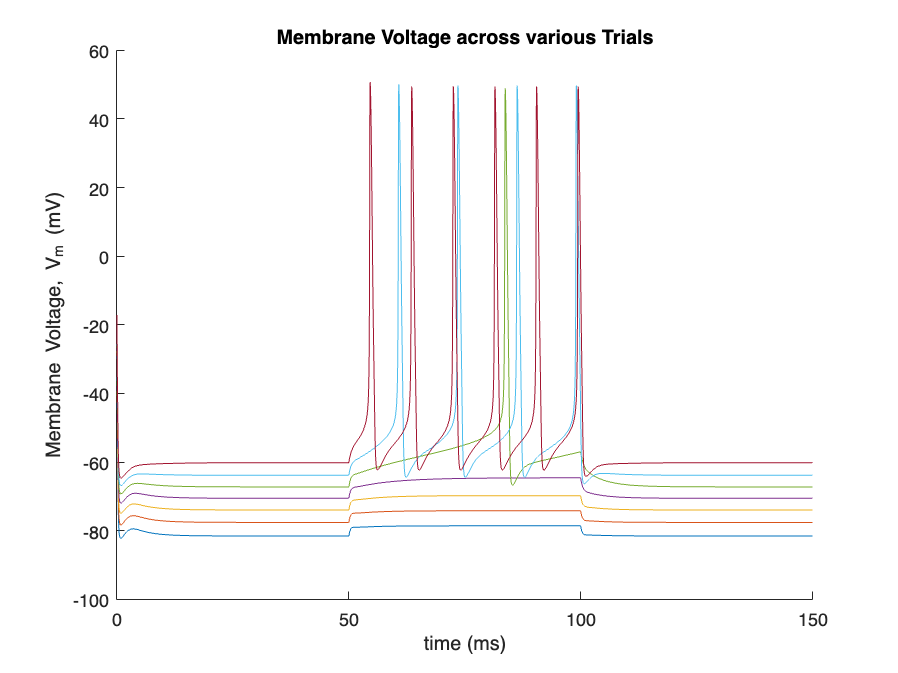


for trial = 1 : length(E_K)
    for t = 1 : length(time) - 1
        %computing voltage dependent variables
        %table 4.4, slightly modified to acocunt for change in parameters
        alpha_m = (0.38 .*(V_m(t) + 29.7))./(1-exp(-0.1 .* (V_m(t) + 29.7)));
        beta_m = (15.2) .* (exp(-0.0556 .* (V_m(t) + 54.7)));
    
        alpha_h = 0.266 .* (exp(-0.05 .*(V_m(t) + 48)));
        beta_h = (3.8) ./(1+ exp(-0.1 .*(V_m(t) + 18)));

        alpha_n = (0.02 .*(V_m(t)+45.7))./(1-exp(-0.1 .*(V_m(t)+ 45.7)));
        beta_n = 0.25 .* (exp(-0.0125.*(V_m(t)+ 55.7)));

        %rate constants for A
        a_inf = (0.0761 .*(exp(0.0314*(V_m(t)+94.22)))./(1+exp(0.0346 .*(V_m(t)+ 1.17)))).^(1/3);
        tau_a = (0.3632 + 1.158)./(1+exp(0.0497.*(V_m(t)+ 55.96)));
    
        b_inf = ((1)./(1+exp(0.0688*(V_m(t)+ 53.3)))).^4;
        tau_b = (1.24 + 2.678) ./(1+exp(0.0624.*(V_m(t)+ 53.3)));

        %steady states
        m_ss = alpha_m / (alpha_m + beta_m);
        h_ss = alpha_h / (alpha_h + beta_h);
        n_ss = alpha_n / (alpha_n + beta_n);

        if t == 1
            m(1) = m_ss;
            h(1) = h_ss;
            n(1) = n_ss;
            a(1) = a_inf;
            b(1) = b_inf;
        end

        %calculating gating variables
        dm = (alpha_m * (1 - m(t)) - (beta_m * m(t)))*dt;
        m(t+1) = m(t) + dm;

        dn = (alpha_n * (1 - n(t)) - (beta_n * n(t)))*dt;
        n(t+1) = n(t) + dn;

        dh = (alpha_h * (1 - h(t)) - (beta_h * h(t)))*dt;
        h(t+1) = h(t) + dh;

        da = ((a_inf - a(t)) ./ tau_a) .* dt ;
        a(t+1)= a(t) + da ;

        db = ((b_inf - b(t)) ./ tau_b) .* dt ;
        b(t+1)= b(t) + db ;

        %Calculating the currents for the various ions
        I_leak = - G_leak * (E_leak - V_m(t));
        I_Na = - G_Na_max .* m(t).^3 * h(t) .* (E_Na - V_m(t));
        I_K = -G_K_max .* n(t).^4 .*(E_K(trial) - V_m(t));
        I_A = -G_A_max * a(t).^3 .* b(t) .* (E_A(trial) - V_m(t));
    
        %differential equation of voltage
        dV = ((-I_leak - I_Na -I_K - I_A + I_app(t)) / C_m) * dt;
        V_m(t + 1) = V_m(t) + dV;

    end
    hold on
    plot(time, V_m)
    xlabel('time (ms)')
    ylabel('Membrane Voltage, V_m (mV)')
    title('Membrane Voltage across various Trials')

    AP_peak(trial) = max(V_m);
end

#### Plotting the Figures

The first graph plots the various membrane voltages against time. This graph is meant to display how the action potential changes based on the reversal potentials of the $K^{+\;}$and $A$ channels. 

The second graph demonstrates the applied current used in the experiment.

The third graph plots AP_peak against time to show how the action potential height varies with potassium concentration. 

The fourth graph is a visual representation of the relationship between potassium concentration and the reversal potential for the  $K^{+\;}$and $A$ channels.

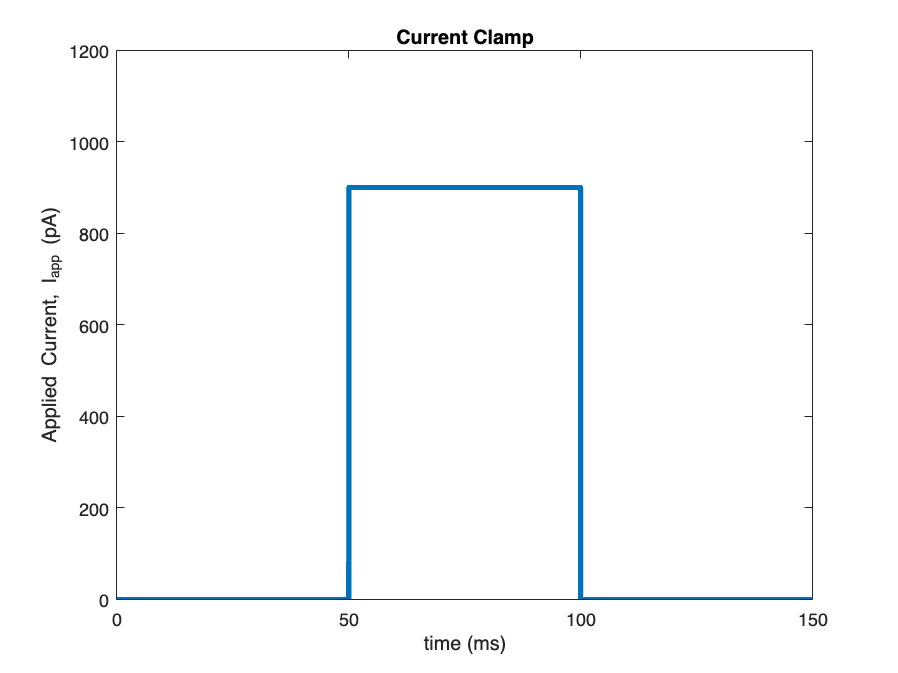

figure
plot(time, I_app, 'Linewidth', 3)
xlabel('time (ms)')
ylabel('Applied Current, I_{app} (pA)')
title('Current Clamp')
ylim([0 1200])

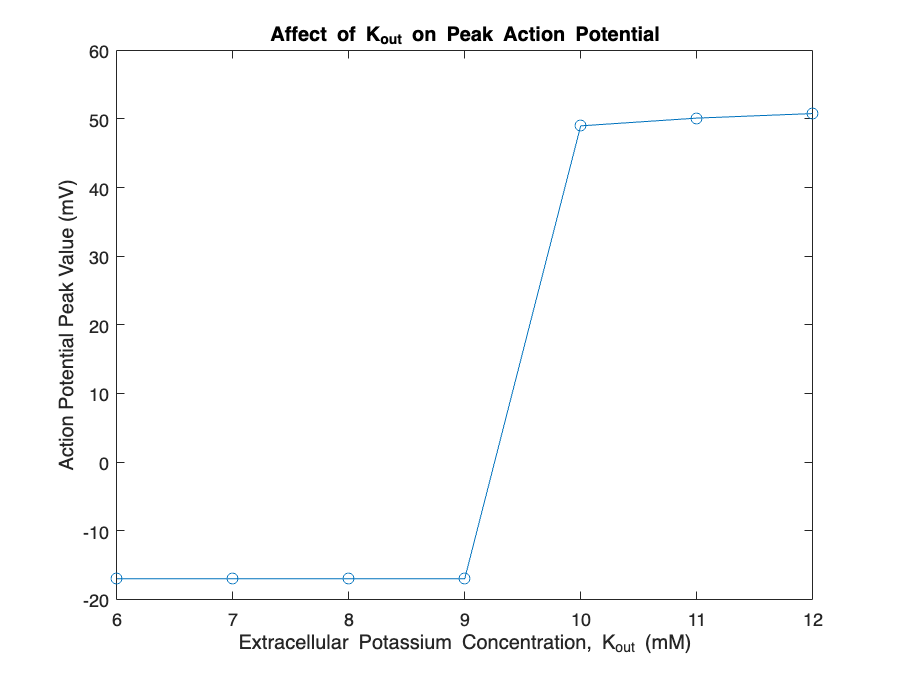


figure
plot(K_out, AP_peak, '-o')
xlabel('Extracellular Potassium Concentration, K_{out} (mM)')
ylabel('Action Potential Peak Value (mV)')
title('Affect of K_{out} on Peak Action Potential')

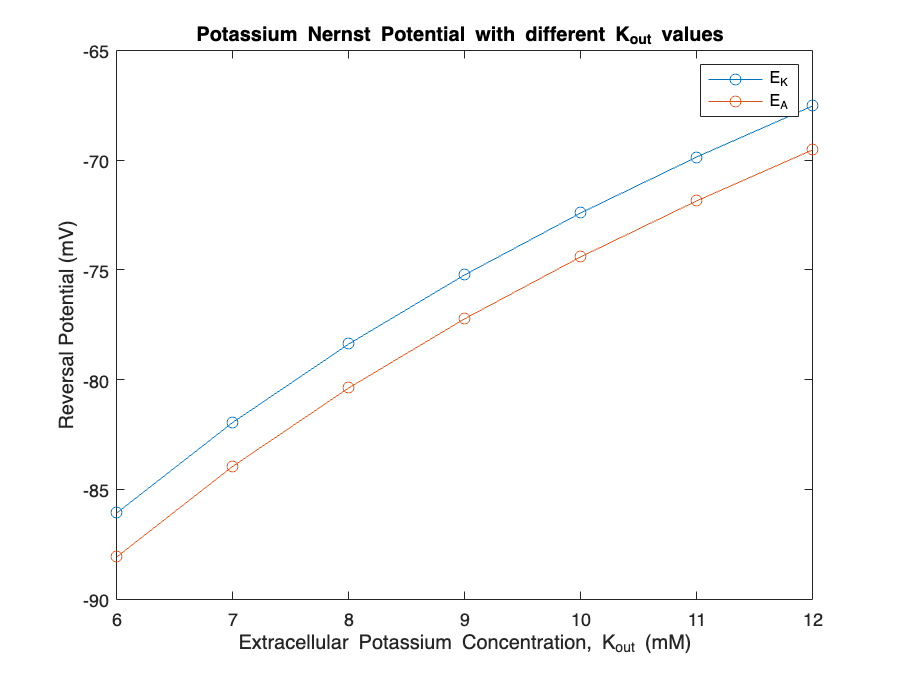


figure
plot(K_out, E_K, '-o')
hold on
plot(K_out, E_A, '-o')

xlabel('Extracellular Potassium Concentration, K_{out} (mM)')
ylabel('Reversal Potential (mV)')
title('Potassium Nernst Potential with different K_{out} values ')
legend('E_K', 'E_A')

#### Conclusion

    As the concentration of the extracellular potassium increases, the potassium reversal potential becomes more positive. The rate of the potassium channel current is influenced by the driving force, denoted as $E_k -V_m$ in the formula. As the reversal potential becomes more positive, the difference between the reversal potential and the membrane voltage becomes greater. Thus, the driving force increases the overall current of the potassium channel, which drives more potassium ions to leave the neuron during the repolarization phase. 

    Note that the first four trials don't produce action potential spikes. In these trials, $E_k$is more negative than its typical value of -72 mV. There is a reduced driving force, thus more potassium ions remain in the neuron. The outward current of potassium is not signficant enough to repolarize the ion. This results in the neuron failing to produce an action potential and the membrane voltage is driven closer to the reversal potential of the leak channels as there are no other strong influences that drive the voltage. 

    The sharp increase seen in the third graph can be attributed to the potassium channels reaching a reversal potential that is equal to or greater than its typical value of -72 mV. As mentioned previously, increasing $E_k$ increases the driving force of the potassium current. Since more potassium ions are flowing outward, the action potential is able to more rapidly repolarize, thus returning the membrane potential to its resting state faster. The membrane potential also approaches the sodium reversal potential. However, it appears to plateau before reaching -55 mV which may be due to the interplay between the various ion currents. 